## Final Exam

**Problem 1:**

(a). Use any method to generate a random sample of size 100 from EV(a = 2, b = 1), where a is the location parameter and b is the scale parameter. Plot the density histogram of the random sample with the true density superimposed. Provide the emprical and theoretical CDF and compare.

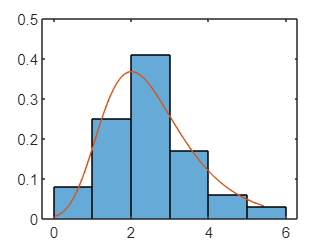

n = 100; data = gevrnd(0,1,2,1,n); % generate values

% plotting histogram with true density superimposed
x1 = min(data):0.1:max(data); y1 = gevpdf(x1,0,1,2);
histogram(data, "Normalization","probability")
hold on
plot(x1,y1)
hold off

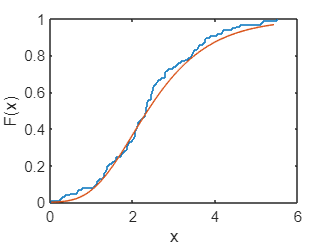


% plotting the ecdf and cdf
y2 = gevcdf(x1,0,1,2);
ecdf(data)
hold on
plot(x1,y2)
hold off

(b) Using the random sample in (a), construct a MC for the location parameter a assuming b = 1. Plot the MC and the density histogram after burn-in. Give the mean, standard deviation, and 95% percentile interval for a. Discuss findings.

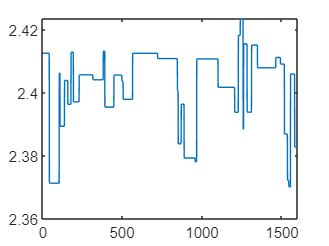

% calculate scott's h
sigHat = std(data);
iqr = quantile(data, 0.75) - quantile(data, 0.25); 
iqr = iqr/1.34;
val = min(sigHat, iqr); hN = 1.06*val*n^(-1/5);

% initialize parameters and likelihood
m = 2000; MC1 = zeros(1,m); MC1(1) = rand; burn = 0.2*m;
L = @(a) exp(n*a-sum(data))*exp(-exp(n*a-sum(data)));

% MC generation
for i = 2:m
    y = normrnd(2,hN); % symmetric proposal dist
    u = rand; % variate for comparison
    
    % calculating alpha
    alpha = min([1,L(y)/L(MC1(i-1))]);
    if u <= alpha
        MC1(i) = y;
    else
        MC1(i) = MC1(i-1);
    end
end

MC1 = MC1(burn+1:m);

% plots and info
plot(MC1)

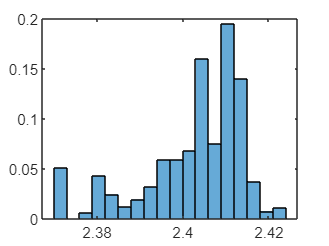

histogram(MC1, "Normalization","probability")

MC1_mean = mean(MC1)

MC1_mean = 2.4025

MC1_std = std(MC1)

MC1_std = 0.0119


% percentile CI
MC1_sort = sort(MC1);
lowCI = MC1(round(0.025*length(MC1_sort)));
uppCI = MC1(round(0.975*length(MC1_sort)));
CI = [lowCI, uppCI]

CI =     2.4126    2.4059


**Problem 2:**

It is known that the distribution of waiting times between events in a Poisson process with intensity $\lambda$ are $Exp(\lambda)$. We would like to use this fact to generate random numbers from $Poisson(\lambda)$. Generate events $E_i=\sum Y_j$ , $Y_j \sim Exp(\lambda)$ and then take $X = \#\{E_i :E_i \in [0,1]}$ as $Possion(\lambda)$ pseudo-rv's.

(a) Write a function to generate N such random numbers. Using your function, generate $N=1000$ such random numbers with $\lambda=3$. Provide the density histogram of the random sample and superimpose the theoretical density. Discuss findings.

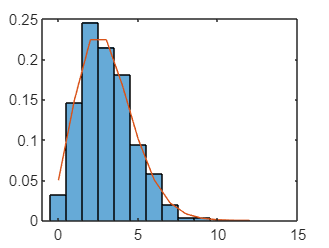

% part a
n = 1000;
funcPois = expPois(3,n); % variables from func

% plots
histogram(funcPois, "normalization","probability")
hold on
dom = 0:1:12;
range = poisspdf(dom,3);
plot(dom,range)
hold off

(b) Use the kernel density estimation method to estimate probability density at $x=0,1,...,12$. Compare with true density numerically and graphically.

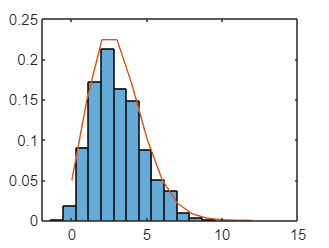

% part b
kdePois = kdeDataGen(funcPois, n); % using data from a

% graphical comparison
h = histogram(kdePois, 13, 'Normalization','probability');
hold on
plot(dom,range)
hold off


% numerical comparison
histFreq = h.BinCounts/n;
MSE = (1/13)*sum((range-histFreq).^2)

MSE = 0.0048

(c) Do Monte Carlo simulation to estimate MSE at each point $x=0,1,2,...,12$. Carefully discuss findings.

% part c

% initializing
M = 100; points = 13; MC_MSE = zeros(points,M);

% Monte Carlo simulation on MSE across 13 points
for i = 1:points
    for j = 1:M
        kdeSet = kdeDataGen(funcPois, n);
        [count, edge] = histcounts(kdeSet, points);
        MC_MSE(i,j) = ((count(i)/n)-range(i))^2;
    end
end

for i = 1:points
   mean(MC_MSE(i,:))
end

ans = 0.0018

ans = 0.0136

ans = 0.0154

ans = 0.0037

ans = 7.5574e-04

ans = 0.0049

ans = 0.0078

ans = 0.0046

ans = 0.0023

ans = 8.3471e-04

ans = 1.8501e-04

ans = 1.9019e-05

ans = 1.5279e-05

**EXTRA CREDIT**

Use Gibbs sampler to generate bivariate MC, $\[M=\left[ {\begin{array}{c}X \\ Y \\ \end{array} } \right]\]$ of size 5000 from a bivariate mixture normal with given values (see doc). Burn-in 10% and plot MC and histogram. Give the scatterplot of X vs Y.

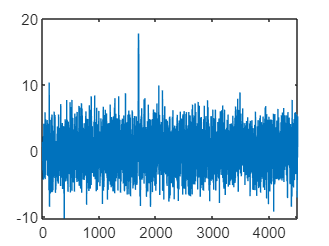

% initializing everything
N = 5000; burn = 0.1*N; X = zeros(1,N); Y = zeros(1,N);
mu1 = [0;-2]; mu2 = [15;10]; p = 0.3; 
sig1 = [3 1;1 3]; sig2 = [2 1;1 2];
X(1) = normrnd(0, sqrt(15)); Y(1) = normrnd(-2, sqrt(10));

wx = @(x) (p*3^(-0.5)*exp(-(x-mu1(1)).^2/6))/(p*3^(-0.5)*exp(-(x-mu1(1)).^2/6) + (1-p)*2^(-0.5)*exp(-(x-mu2(1)).^2/4));
wy = @(y) (p*3^(-0.5)*exp(-(y-mu1(2)).^2/6))/(p*3^(-0.5)*exp(-(y-mu1(2)).^2/6) + (1-p)*2^(-0.5)*exp(-(y-mu2(1)).^2/4));

% Gibbs Sampling Process
for i = 2:N
    X(i) = wy(Y(i-1))*normrnd(mu1(1)+(Y(i-1)-mu1(2))*(1/3), det(sig1)/3) + ...
       (1-wy(Y(i-1)))*normrnd(mu2(1)+(Y(i-1)-mu2(2))*(1/2), det(sig2)/2); 
    Y(i) = wx(X(i))*normrnd(mu1(2)+(X(i)-mu1(1))*(1/3), det(sig1)/3) + ...
       (1-wy(Y(i-1)))*normrnd(mu2(2)+(X(i)-mu2(1))*(1/2), det(sig2)/2);  
end

% adjustments and plots
X = X(burn+1:N); Y = Y(burn+1:N);

plot(X)

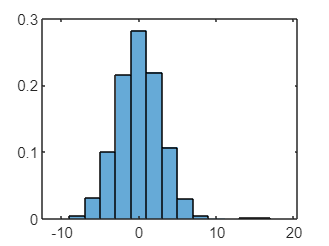

histogram(X,15,"Normalization","probability")

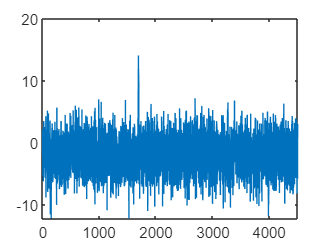


plot(Y)

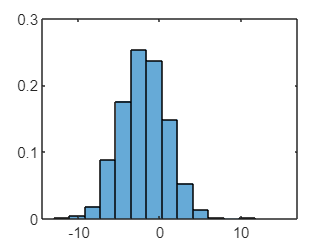

histogram(Y,15,"Normalization","probability")

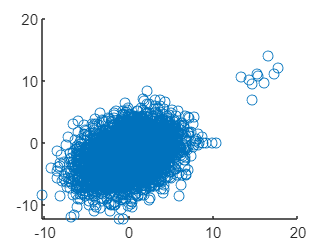


scatter(X,Y)